# Loop Statement

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2019-04-29

## Review: Relational Expressions

is_true01 = (3> 3)
is_true02 = (3>= 3)
is_true03 = (3 == 3)
is_true04 = ('a' == 3)
is_true05 = ('a' == 97)
is_true06 = or((3>4), (4>3))
is_true07 = ((3>4)||(4>3))
is_true08 = and((3>4), (4>3))
is_true09 = ((3>4)&&(4>3))
is_true10 = xor((3>4), (4>3))

### List of 'is' functions

### isscalar, isvector, and ismatrix

- A scalar is considered to be a 1 x 1 vector or 1 x 1 matrix.

- A n x 1 vector is considered to be a n x 1 matrix.

is_scalar1 = isscalar(3)
is_scalar2 = isscalar([1 2 ])
is_scalar3 = isscalar([1 2;3 4])
is_scalar4 = isscalar('ab')

unknown_val = 3;
is_scalar5 = (numel(unknown_val)==1)

is_vector1 = isvector(3)
is_vector2 = isvector([1 2 ])
is_vector3 = isvector([1 2;3 4])
is_vector4 = isvector('ab')

is_matrix1 = ismatrix(3)
is_matrix2 = ismatrix([1 2 ])
is_matrix3 = ismatrix([1 2;3 4])
is_matrix4 = ismatrix('ab')

### isrow and iscolumn

vec1 = ones(3,1);

is_row1 = isrow(vec1)
is_row2 = isrow(vec1')
is_row3 = isrow(2)
is_row4 = (size(vec1,1) == 1)

is_column1 = iscolumn(vec1)
is_column2 = iscolumn(vec1')
is_column3 = iscolumn(3)
is_column4 = (size(vec1,2) == 1)

### isempty 

vec1 = [1 2 3];
is_empty1 = isempty([]);

vec2 = vec1;
vec2(1:end) = [];
is_empty2 = isempty(vec2);

vec3 = find(vec1 == 4);
is_empty3 = isempty(vec3);

is_empty1
is_empty2
is_empty3

#### ischar, isletter, and isspace

is_char1 = ischar('a')
is_char2 = ischar(97)
is_char3 = ischar(char(97))

is_letter1 = isletter('a')
is_letter2 = isletter('ab')
is_letter3 = isletter('a2b')
is_letter4 = isletter('a2 b')

val = int8(' ')
is_space1 = isspace('a')
is_space2 = isspace('a b')
is_space3 = isspace('ab ')
is_space4 = isspace('ab ')

## if Statement

% example 1: isscalar
x = 10;
is_scalar1 = isscalar(x);

is_scalar2 = false;
if numel(x)==1
    is_scalar2 = true;
end

is_scalar3 = (numel(x)==1);

is_scalar1
is_scalar2
is_scalar3

% example 2: quiz
true_answer = 10;
your_answer = 11;

is_correct1 = false;
if your_answer == true_answer
    is_correct = true;
end

is_correct2 = (your_answer == true_answer);

is_correct1
is_correct2

## if-else Statement

### Simple example

% example 1: isscalar

x = 10;
is_scalar1 = isscalar(x);
is_scalar2 = [];
if numel(x) == 1
    is_scalar2 = true;
    disp('x is a scalar.');
else
    is_scalar2 = false;
    disp('x is not a scalar.');
end
% comment: if there are muliple actions needed, you need to introduce else.
% In additions, sometimes it is good to explicilty assign values (like
% is_slcalar2 = false) rather than remaining a intial value unchanged.

is_scalar1
is_scalar2

### Example: Rectified Linear Units

Q: Please write a code to replicate this function


$$f\left(x\right)=\mathrm{max}\left(0,x\right)$$


x = 10;
if x<0
    fx1 = 0;
else
    fx1 = x;
end

fx2 = x*(x>0);

x = -10;
if x<0
    fx3 = 0;
else
    fx3 = x;
end

fx4 = x*(x>0);

fx1
fx2
fx3
fx4

### Example: L'Hôpital's rule

Q: Please write a code to compute $\frac{\mathrm{sin}\;x}{x}$ given x. (Hint: we can't compute it when x is 0)

% THINK ABOUT YOUR ANSER BEFORE LOOKING AT SAMPLE CODES

tol = 10^-4;
x = 10; 
val1 = sin(x)/x;

% however, val1 becomes NaN if x is zero.

% A correct solution is
x = 10;
if abs(x)<tol
    x = tol;
end
val2 = sin(x)/x;

x = 0;
if abs(x)<tol
    x = tol;
end
val3 = sin(x)/x;

x = 0;
val5 = cos(x);


val6 = my_sinc_fun(10);
val7 = my_sinc_fun(0);

val1
val2
val3
val4
val5
val6
val7

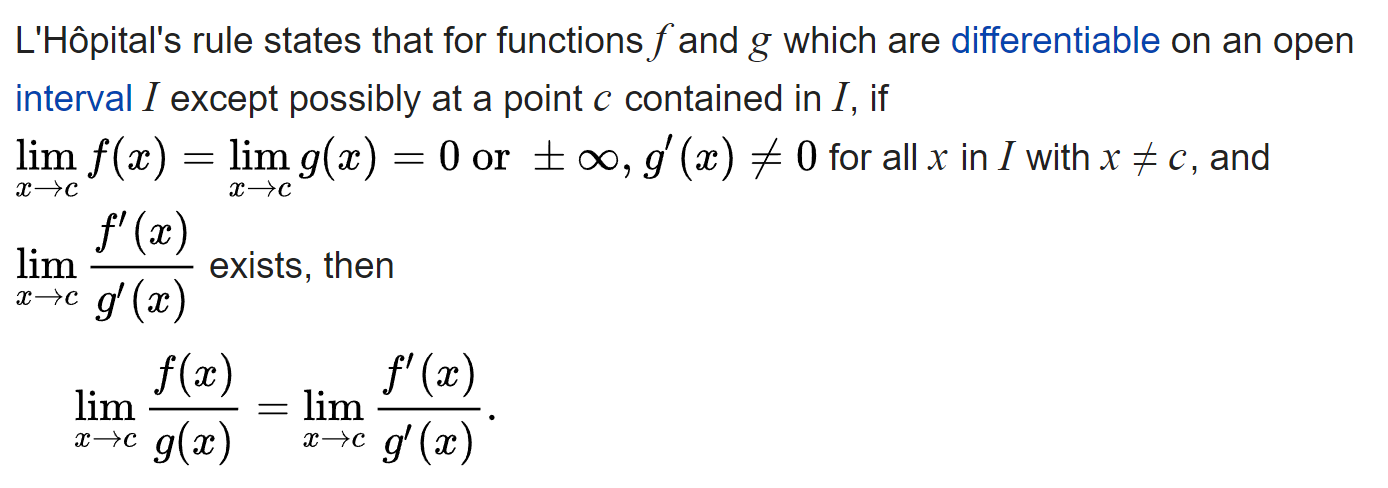

### Example: Check a dimension of your input

Q: Write a code to check your input vector is a 1x5 row vector

x = rand(5,1);
% x = rand(1,5);

check_error1 = 0;
if ~isrow(x) || (numel(x)~=5)
    check_error1 = 1;
end
   
check_error2 = 0;
if ~((size(x,1)==1) && (size(x,2) == 5))
    check_error2 = 1;
end

check_error3 = 0;
if ~and(isrow(x), (numel(x)==5))
    check_error3 = 1;
end

check_error4 = 0;
if ~isequal(size(x), [1 5])
    check_error4 = 1;
end

check_error1
check_error2
check_error3
check_error4

### Throwing an Error

x = rand(1,5);
if ~isequal(size(x), [1 5])
    error('incorrect dimension of x')
end
assert(isequal(size(x), [1 5]), 'incorrect dimension of x');

x = rand(5,1);
% if ~isequal(size(x), [1 5])
%     error('incorrect dimension of x')
% end
assert(isequal(size(x), [1 5]), 'incorrect dimension of x');

## Nested if-else, elseif, and switch Statement

### Nested if-else and elseif statement

Q: Write a program that gives a grade based on a score. A: >=90, B: 80~90, C:70~80, D: <70

score = 61;
garde1 = [];
if score>=90
    grade1 = 'A';
else
    if score>=80
        grade1 = 'B';
    else
        if score >=70
            grade1 = 'C';
        else
            grade1 = 'D';
        end
    end
end

grade2 = [];
if score>=90
    grade2 = 'A';
elseif and(score>=80, score<90)
    grade2 = 'B';
elseif and(score>=70, score<80)
    grade2 = 'C';
else
    grade2 = 'D';
end

grade1
grade2

grade3 = myfun_grade(30)
grade4 = myfun_grade(98)
grade5 = myfun_grade(76)

### elseif statement

score = 85;

% this is a wrong example
if score >= 70
    disp('Your grade is C.');
elseif score > 80
    disp('Your grade is B.');
elseif score > 90
    disp('Your grade is A.');
else
    disp('Your grade is D.');
end

Your grade is C.



% correct
if score < 70 
    disp('Your grade is D.');
elseif score < 80
    disp('Your grade is C.');
elseif score < 90
    disp('Your grade is B.');
else
    disp('Your grade is A.');
end

Your grade is B.



% comment: if-elseif statement conducts only one action and does not
% excuate the rest of statement. 

### **Switch statement**

Q: Let's write a code for conducting an opposite action. A program tells you the score range when you type your grade. 

grade = 'A';

if grade == 'A'
    disp('Your score is in the range of 90-100.');
elseif grade == 'B'
    disp('Your score is in the range of 80-90.');
elseif grade == 'C'
    disp('Your score is in the range of 70-80.');
elseif grade == 'D'
    disp('Your score is below 70.');
else
    disp('We do not have such grade.')
end

Your score is in the range of 90-100.



switch grade
    case 'A'
        disp('Your score is in the range of 90-100.');
    case 'B'
        disp('Your score is in the range of 80-90.');
    case 'C'
        disp('Your score is in the range of 70-80.');
    case 'D'
        disp('Your score is below 70.');
    otherwise
        disp('We do not have such grade.');
end

Your score is in the range of 90-100.


## User-defined Functions

### myfun_sinc(x)

function val = myfun_sinc(x)
tol = 10^-4;
if abs(x)<tol
    val = cos(x);
else
    val = sin(x)/x;
end
end


### myfun_grade(score)

function grade = myfun_grade(score)
grade = [];
if score>90
    grade = 'A';
elseif and(score>=80, score<90)
    grade = 'B';
elseif and(score>=70, score<80)
    grade = 'C';
else
    grade = 'D';
end

end